# 3-D Brain Tumor Segmentation Using Deep Learning

This example shows how to train a 3-D U-Net neural network and perform semantic segmentation of brain tumors from 3-D medical images.

## Download Training, Validation, and Test Data

Create a directory to store the BraTS data set.

imageDir = fullfile("C:\Users\AppliedResearch\Downloads\Task01_BrainTumour\");

## Preprocess Training and Validation Data

To train the 3-D U-Net network more efficiently, preprocess the MRI data using the helper function `preprocessBraTSDataset`. This function is attached to the example as a supporting file. The helper function performs these operations:

- Crop the data to a region containing primarily the brain and tumor. Cropping the data reduces the size of data while retaining the most critical part of each MRI volume and its corresponding labels.

- Normalize each modality of each volume independently by subtracting the mean and dividing by the standard deviation of the cropped brain region.

sourceDataLoc = imageDir+filesep+"Task01_BrainTumour";
preprocessDataLoc = imageDir+filesep+"preprocessedDataset";
preprocessBraTSDataset(preprocessDataLoc,sourceDataLoc);

## Create Random Patch Extraction Datastore for Training and Validation

Use a random patch extraction datastore to feed the training data to the network and to validate the training progress.

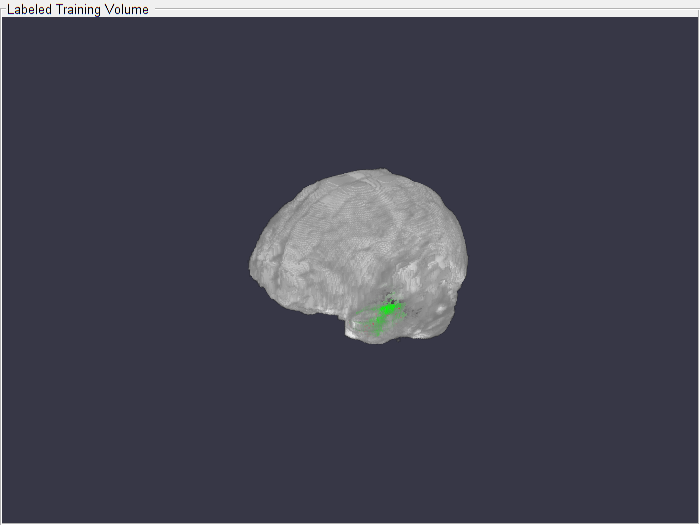

volLoc = fullfile(preprocessDataLoc,"imagesTr");
volds = imageDatastore(volLoc,FileExtensions=".mat",ReadFcn=@matRead);

% create datastore 
lblLoc = fullfile(preprocessDataLoc,"labelsTr");
classNames = ["background","edema","neTumor","eTumor"];
pixelLabelID = [0 1 2 3];
pxds = pixelLabelDatastore(lblLoc,classNames,pixelLabelID, ...
    FileExtensions=".mat",ReadFcn=@matRead);

% preview
volume = preview(volds);
label = preview(pxds);

viewPnl = uipanel(figure,Title="Labeled Training Volume");
hPred = labelvolshow(label,volume(:,:,:,1),Parent=viewPnl,LabelColor=[0 0 0;1 0 0;0 1 0; 0 0 1]);

hPred.LabelVisibility = logical([1; 1; 1; 1]);

patchSize = [132 132 132];
patchPerImage = 16;
miniBatchSize = 4;

patchds = randomPatchExtractionDatastore(volds,pxds,patchSize, ...
    PatchesPerImage=patchPerImage);
patchds.MiniBatchSize = miniBatchSize;

volLocVal = fullfile(preprocessDataLoc,"imagesTest");
voldsVal = imageDatastore(volLocVal,FileExtensions=".mat",ReadFcn=@matRead);

lblLocVal = fullfile(preprocessDataLoc,"labelsTest");
pxdsVal = pixelLabelDatastore(lblLocVal,classNames,pixelLabelID, ...
    FileExtensions=".mat",ReadFcn=@matRead);

dsVal = randomPatchExtractionDatastore(voldsVal,pxdsVal,patchSize, ...
    PatchesPerImage=patchPerImage);
dsVal.MiniBatchSize = miniBatchSize;

## Set Up 3-D U-Net

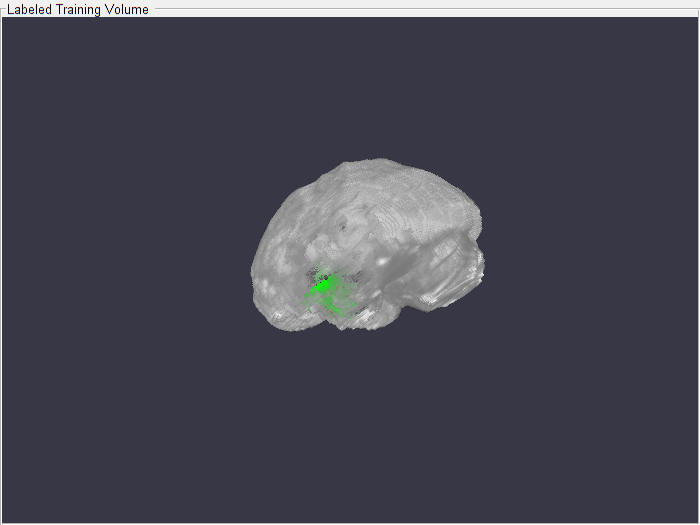

numChannels = 4;
inputPatchSize = [patchSize numChannels];
numClasses = 4;
[lgraph,outPatchSize] = unet3dLayers(inputPatchSize,numClasses,ConvolutionPadding="valid");

% created transformed imagedatastores
dsTrain = transform(patchds,@(patchIn)augmentAndCrop3dPatch(patchIn,outPatchSize,"Training"));
dsVal = transform(dsVal,@(patchIn)augmentAndCrop3dPatch(patchIn,outPatchSize,"Validation"));

% replace output
outputLayer = dicePixelClassificationLayer(Name="Output");
lgraph = replaceLayer(lgraph,"Segmentation-Layer",outputLayer);

% replace input
inputLayer = image3dInputLayer(inputPatchSize,Normalization="none",Name="ImageInputLayer");
lgraph = replaceLayer(lgraph,"ImageInputLayer",inputLayer);


% set training options
options = trainingOptions("adam", ...
    MaxEpochs=50, ...
    InitialLearnRate=5e-4, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropPeriod=5, ...
    LearnRateDropFactor=0.95, ...
    ValidationData=dsVal, ...
    ValidationFrequency=10000, ...
    Plots="training-progress", ...
    Verbose=false, ...
    MiniBatchSize=miniBatchSize);

## Download Sample Test Set

imageDir = fullfile(tempdir,"BraTS");
downloadBraTSSampleTestData(imageDir);

inputPatchSize = [132 132 132 4];
outPatchSize = [44 44 44 2];

## Train Network

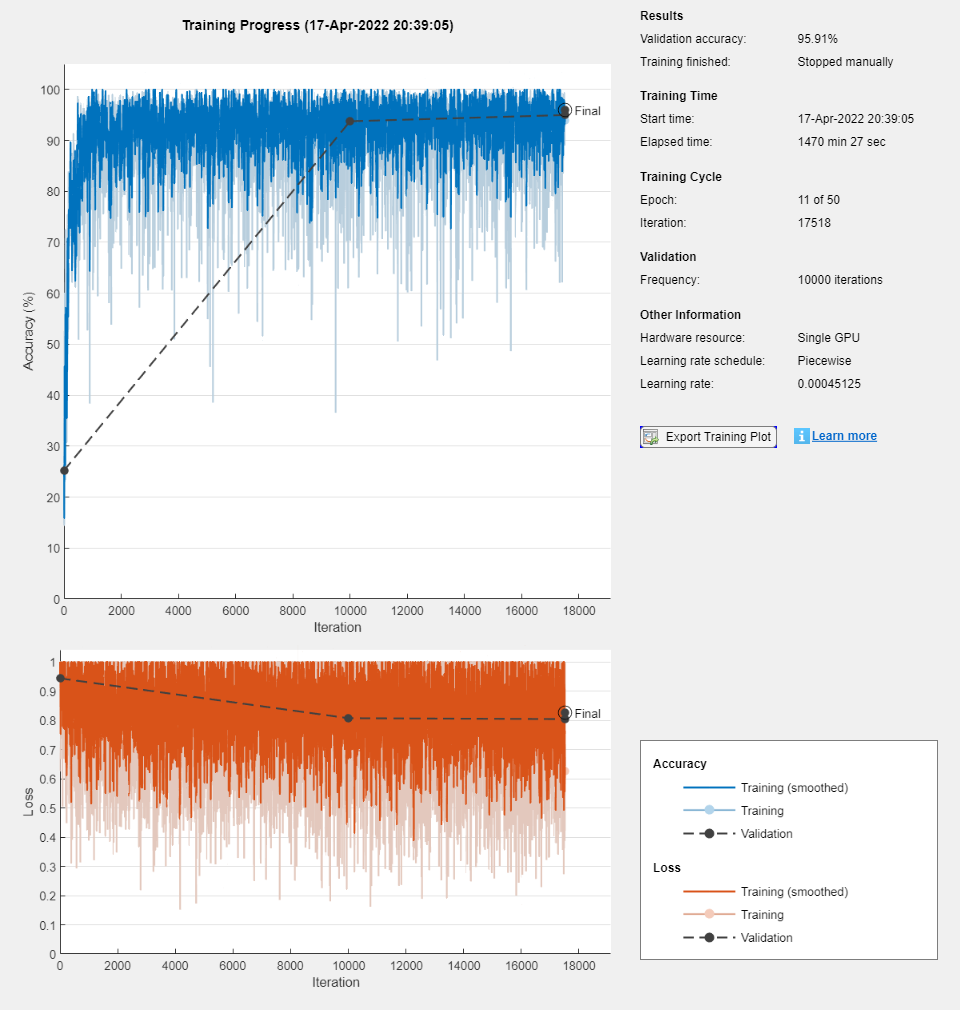

gpuDevice(1);
[net,info] = trainNetwork(dsTrain,lgraph,options);
modelDateTime = string(datetime("now",Format="yyyy-MM-dd-HH-mm-ss"));
save("trained3DUNet-"+modelDateTime+".mat","net");

## Perform Segmentation of Test Data

volLocTest = preprocessDataLoc+filesep+"imagesTest";
lblLocTest = preprocessDataLoc+filesep+"labelsTest";

voldsTest = imageDatastore(volLocTest,FileExtensions=".mat",ReadFcn=@matRead);
pxdsTest = pixelLabelDatastore(lblLocTest,classNames,pixelLabelID, ...
    FileExtensions=".mat",ReadFcn=@matRead);

id = 1;
while hasdata(voldsTest)
    disp("Processing test volume "+num2str(id));
    
    tempGroundTruth = read(pxdsTest);
    groundTruthLabels{id} = tempGroundTruth{1};
    vol{id} = read(voldsTest);
    
    % Use reflection padding for the test image. 
    % Avoid padding of different modalities.
    volSize = size(vol{id},(1:3));
    padSizePre  = (inputPatchSize(1:3)-outPatchSize(1:3))/2;
    padSizePost = (inputPatchSize(1:3)-outPatchSize(1:3))/2 + ...
        (outPatchSize(1:3)-mod(volSize,outPatchSize(1:3)));
    volPaddedPre = padarray(vol{id},padSizePre,"symmetric","pre");
    volPadded = padarray(volPaddedPre,padSizePost,"symmetric","post");
    [heightPad,widthPad,depthPad,~] = size(volPadded);
    [height,width,depth,~] = size(vol{id});
    
    tempSeg = categorical(zeros([height,width,depth],"uint8"),[0;1;2;3],classNames);
    
    % Overlap-tile strategy for segmentation of volumes.
    for k = 1:outPatchSize(3):depthPad-inputPatchSize(3)+1
        for j = 1:outPatchSize(2):widthPad-inputPatchSize(2)+1
            for i = 1:outPatchSize(1):heightPad-inputPatchSize(1)+1
                patch = volPadded( i:i+inputPatchSize(1)-1,...
                    j:j+inputPatchSize(2)-1,...
                    k:k+inputPatchSize(3)-1,:);
                patchSeg = semanticseg(patch,net);
                tempSeg(i:i+outPatchSize(1)-1, ...
                    j:j+outPatchSize(2)-1, ...
                    k:k+outPatchSize(3)-1) = patchSeg;
            end
        end
    end
    
    % Crop out the extra padded region.
    tempSeg = tempSeg(1:height,1:width,1:depth);

    % Save the predicted volume result.
    predictedLabels{id} = tempSeg;
    id=id+1;
end

Processing test volume 1
Processing test volume 2
Processing test volume 3
Processing test volume 4
Processing test volume 5
Processing test volume 6
Processing test volume 7
Processing test volume 8
Processing test volume 9
Processing test volume 10
Processing test volume 11
Processing test volume 12
Processing test volume 13
Processing test volume 14
Processing test volume 15
Processing test volume 16
Processing test volume 17
Processing test volume 18
Processing test volume 19
Processing test volume 20
Processing test volume 21
Processing test volume 22
Processing test volume 23
Processing test volume 24
Processing test volume 25
Processing test volume 26
Processing test volume 27
Processing test volume 28
Processing test volume 29
Processing test volume 30
Processing test volume 31
Processing test volume 32
Processing test volume 33
Processing test volume 34
Processing test volume 35
Processing test volume 36
Processing test volume 37
Processing test volume 38
Processing test volum

volId = 1;
vol3d = vol{volId}(:,:,:,1);

zID = size(vol3d,3)/2;
zSliceGT = labeloverlay(vol3d(:,:,zID),groundTruthLabels{volId}(:,:,zID));
zSlicePred = labeloverlay(vol3d(:,:,zID),predictedLabels{volId}(:,:,zID));

figure
montage({zSliceGT,zSlicePred},Size=[1 2],BorderSize=5) 

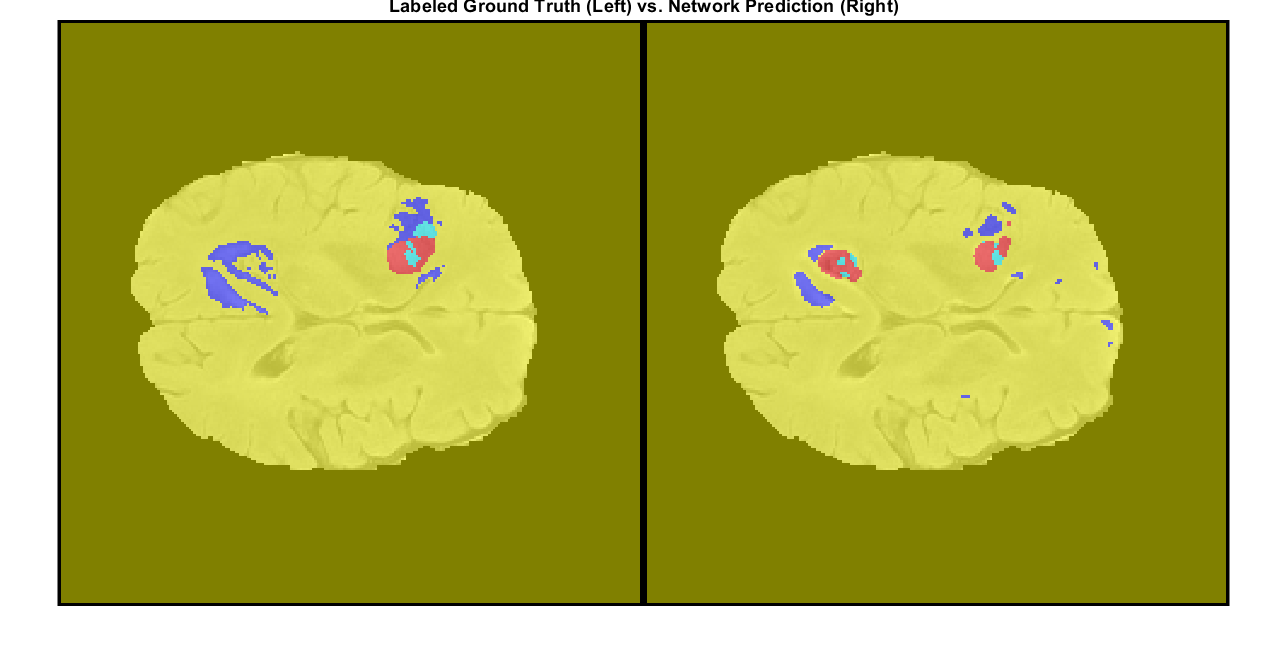

title("Labeled Ground Truth (Left) vs. Network Prediction (Right)")

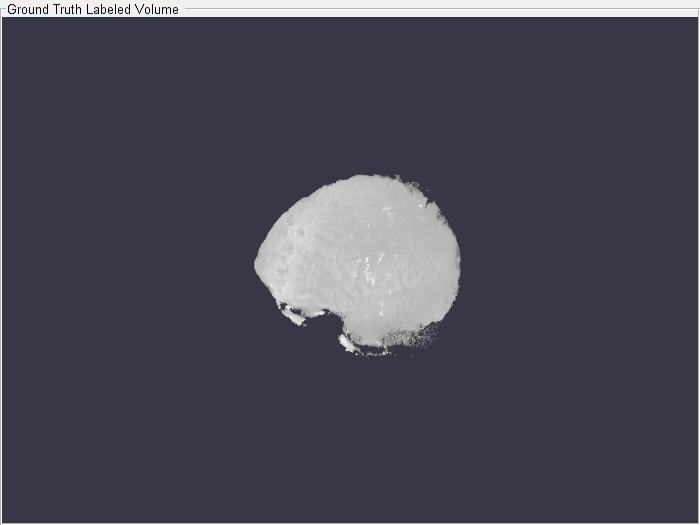

viewPnlTruth = uipanel(figure,Title="Ground Truth Labeled Volume");
hTruth = labelvolshow(groundTruthLabels{volId},vol3d,Parent=viewPnlTruth, ...
    LabelColor=[0 0 0;1 0 0; 0 1 0; 0 0 1],VolumeThreshold=0.68);

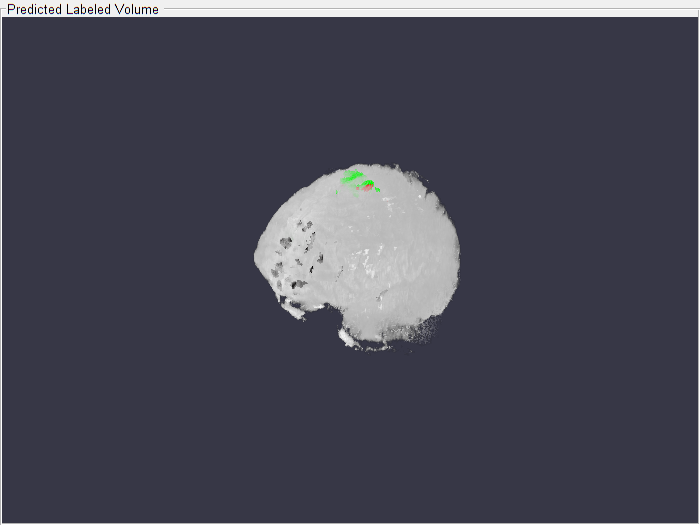

hTruth.LabelVisibility = logical([1; 1; 1; 1]);

viewPnlPred = uipanel(figure,Title="Predicted Labeled Volume");
hPred = labelvolshow(predictedLabels{volId},vol3d,Parent=viewPnlPred, ...
    LabelColor=[0 0 0;1 0 0;0 1 0; 0 0 1],VolumeThreshold=0.68);

hPred.LabelVisibility = logical([1; 1; 1; 1]);

## Quantify Segmentation Accuracy

Measure the segmentation accuracy using the [`dice`](docid:images_ref#mw_1ee709d7-bf6b-4ac9-8f5d-e7caf72497d4) function. This function computes the Dice similarity coefficient between the predicted and ground truth segmentations.

diceResult = zeros(length(voldsTest.Files),4);

for j = 1:length(vol)
    diceResult(j,:) = dice(groundTruthLabels{j},predictedLabels{j});
end
meanDiceBackground = mean(diceResult(:,1));
disp("Average Dice score of background across "+num2str(j)+ ...
    " test volumes = "+num2str(meanDiceBackground))

Average Dice score of background across 50 test volumes = 0.99781


meanDiceTumor = mean(diceResult(:,2));
disp("Average Dice score of tumor across "+num2str(j)+ ...
    " test volumes = "+num2str(meanDiceTumor))

Average Dice score of tumor across 50 test volumes = 0.61932


meanDiceTumor = mean(diceResult(:,3));
disp("Average Dice score of tumor across "+num2str(j)+ ...
    " test volumes = "+num2str(meanDiceTumor))

Average Dice score of tumor across 50 test volumes = 0.42639



meanDiceTumor = mean(diceResult(:,4));
disp("Average Dice score of tumor across "+num2str(j)+ ...
    " test volumes = "+num2str(meanDiceTumor))

Average Dice score of tumor across 50 test volumes = 0.75465


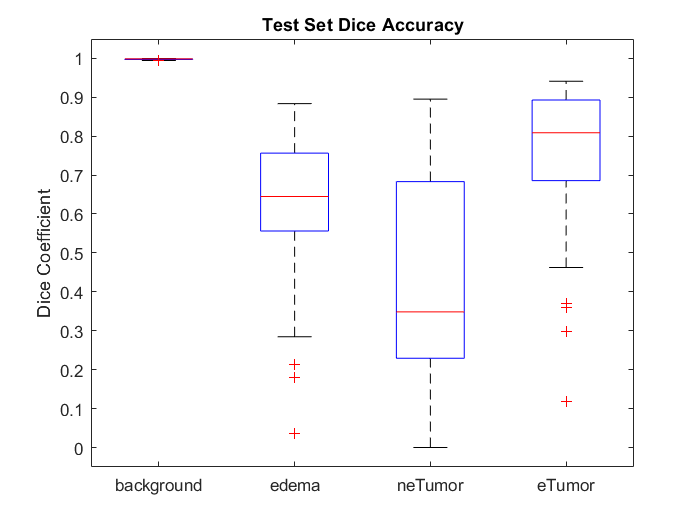


    figure; boxplot(diceResult);
    title("Test Set Dice Accuracy");
    xticklabels(classNames);
    ylabel("Dice Coefficient");

## References

[1] Çiçek, Ö., A. Abdulkadir, S. S. Lienkamp, T. Brox, and O. Ronneberger. "3D U-Net: Learning Dense Volumetric Segmentation from Sparse Annotation." In *Proceedings of the International Conference on Medical Image Computing and Computer-Assisted Intervention - MICCAI 2016*. Athens, Greece, Oct. 2016, pp. 424-432.

[2] Isensee, F., P. Kickingereder, W. Wick, M. Bendszus, and K. H. Maier-Hein. "Brain Tumor Segmentation and Radiomics Survival Prediction: Contribution to the BRATS 2017 Challenge." In *Proceedings of BrainLes: International MICCAI Brainlesion Workshop*. Quebec City, Canada, Sept. 2017, pp. 287-297.

[3] "Brain Tumours". *Medical Segmentation Decathlon.* http://medicaldecathlon.com/ 

The BraTS dataset is provided by Medical Segmentation Decathlon under the [CC-BY-SA 4.0 license.](https://creativecommons.org/licenses/by-sa/4.0/) All warranties and representations are disclaimed; see the license for details. MathWorks® has modified the data set linked in the Download Sample Test Set section of this example. The modified sample data set has been cropped to a region containing primarily the brain and tumor and each channel has been normalized independently by subtracting the mean and dividing by the standard deviation of the cropped brain region.

[4] Sudre, C. H., W. Li, T. Vercauteren, S. Ourselin, and M. J. Cardoso. "Generalised Dice Overlap as a Deep Learning Loss Function for Highly Unbalanced Segmentations." *Deep Learning in Medical Image Analysis and Multimodal Learning for Clinical Decision Support: Third International Workshop*. Quebec City, Canada, Sept. 2017, pp. 240-248.

[5] Ronneberger, O., P. Fischer, and T. Brox. "U-Net:Convolutional Networks for Biomedical Image Segmentation." In *Proceedings of the International Conference on Medical Image Computing and Computer-Assisted Intervention - MICCAI 2015*. Munich, Germany, Oct. 2015, pp. 234-241. Available at arXiv:1505.04597.

*Copyright 2019 The MathWorks, Inc.*